# SAMEKO - Reimbursement rules ERS

WP with Kristofer & Arne

## Input

clear global
clear all
clc

% read regression results
[~,~,~,renewal,MGT,nb_freight_year,nb_pass_year,delay_min,MGT_lifetime,~, ERS] = read_input_data();
switches = 1;% 2 3 4 5 6 7];
renewal = 4.5*10^6; %renewal(1);
headers = {0	5000	7000	8000	10000	18000	20000	22000}';
ERS_levels = 1:length(headers);
korr_main_cost = 8000; % sek per activity, 2014-price level
prev_main_cost = 5000; % sek per activity, 2014-price level
time_horizon_switches_max = 75;
% reconvert to different ERS levels
nb_freight_year = nb_freight_year(switches)*ones(size(headers));
nb_pass_year = nb_pass_year(switches)*ones(size(headers));
delay_min = delay_min(switches)*ones(size(headers));
% MGT_lifetime = MGT_lifetime(switches)*ones(size(headers));
% set parameters
prev_ERS = ERS{1};
korr_ERS = ERS{2};
fail_ERS = ERS{3};
% plot all inputs
data = {prev_ERS, korr_ERS, fail_ERS, headers};
%plot_figure("input-ERS", data);

## LCC 

% LCC for the time_horizon_switches
data_lcc = {prev_ERS,korr_ERS,fail_ERS,nb_freight_year,nb_pass_year,delay_min,time_horizon_switches_max, headers,korr_main_cost,prev_main_cost};
[dir_maint,prev_cap,korr_cap,disr] = assess_lcc(data_lcc);
% plot the yearly undiscounted costs
data = {dir_maint, prev_cap, korr_cap, disr, renewal, headers};
%plot_figure("yearly undiscounted",data);
% annuity
[ann,tpv] = get_ann_tpv(dir_maint, prev_cap, korr_cap, disr, renewal);

## Annuity and optimal lifetime

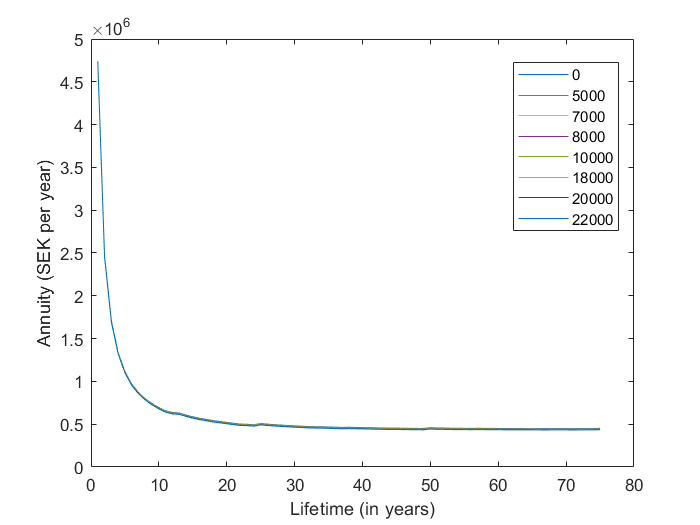

% Find the optimal lifetime (where annuity is minimal)
[optimal_lifetime_switches, min_annuity_switches, annuity_switches] = get_optimal(data_lcc, time_horizon_switches_max, headers, renewal);
% Annuity for switches
data_annuity = {annuity_switches, headers};
plot_figure("annuity-ERS", data_annuity);

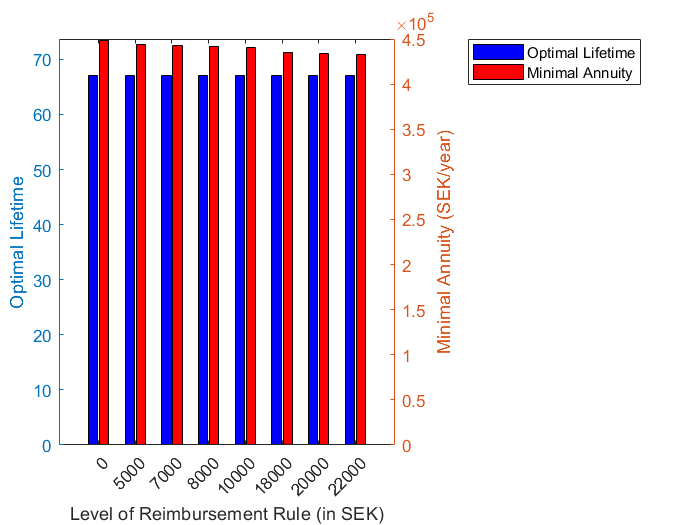

% optimal lifetime
data_figure = {optimal_lifetime_switches, min_annuity_switches, headers};
plot_figure("optimal-lifetime-ERS", data_figure);

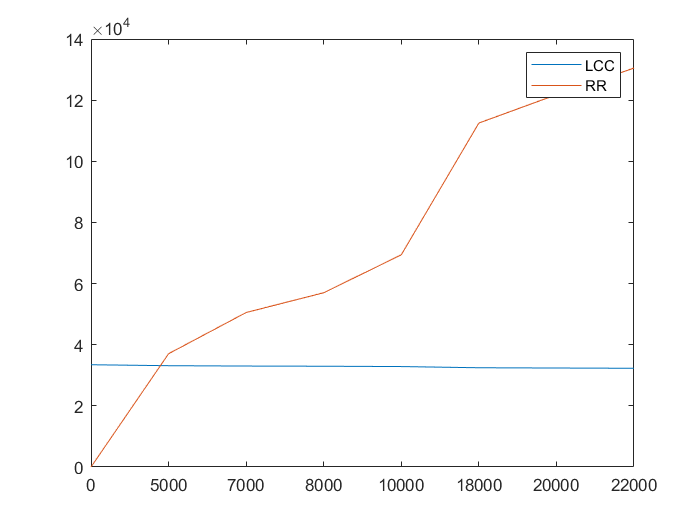

% break-even
contract_years = 5;
data = {min_annuity_switches, headers, contract_years, korr_ERS, optimal_lifetime_switches};
plot_figure("break-even", data);